## 1. gyakorlat

#### 1. Feladat

a) Határozzuk meg az 


$$A=\left[\begin{array}{rrr}
1 & -1 & -1 \\
-1 & 1 & -1 \\
-1 & -1 & 1
\end{array}\right] $$
 

mátrix sajátértékeit és sajátvektorait!

b) Diagonalizálható-e a mátrix? Mennyi a sajátértékek algebrai és geometriai multiplicitása? Mik a sajátalterek?* (Szimmetrikus mátrix, ortogonális mátrixszal diagonalizálható, vannak többszörös sajátértékei.)*

c) Készítsük el MATLABban is a sajátvektorokat, sajátértékeket. Hogyan tudjuk ellenőrizni, hogy a kétdimenziós sajátalterek azonosak (a papíron és a MATLAB által számolt alterek)?

% a)
A=[1,-1,-1; -1,1,-1; -1,-1,1];
D=diag([-1,2,2])

D =     -1     0     0
     0     2     0
     0     0     2


v1=[1,1,1]';
v2=[1,0,-1]';
v3=[1,-1,0]';
V=[v1, v2, v3];
V*D/V

ans =      1    -1    -1
    -1     1    -1
    -1    -1     1



% b)
q1=[1,1,1]'/sqrt(3);
q2=[1,0,-1]'/sqrt(2);
q3=[1,-2,1]'/sqrt(6);

Q=[q1, q2, q3];
Q'*A*Q % visszadja A-t

ans =    -1.0000         0         0
         0    2.0000         0
   -0.0000   -0.0000    2.0000



% c) 
% Megoldás
lambda=eig(A)

lambda =    -1.0000
    2.0000
    2.0000


[VV,DD]=eig(A)

VV =    -0.5774    0.3938   -0.7152
   -0.5774   -0.8163    0.0166
   -0.5774    0.4225    0.6987


DD =    -1.0000         0         0
         0    2.0000         0
         0         0    2.0000


[q2,VV(:,2:3)]

ans =     0.7071    0.3938   -0.7152
         0   -0.8163    0.0166
   -0.7071    0.4225    0.6987


det([q2,VV(:,2:3)])

ans = 2.0027e-17

norm(eye(3)-VV'*VV) % ortogonalitás ellenőrzés

ans = 6.8755e-16

norm(A*VV-VV*DD) % reziduális hiba ellenőrzés

ans = 9.5621e-16

#### 2. Feladat

a) Határozzuk meg a síkon az origó körüli $\varphi$ szöggel (óramutató járásával ellentétesen) való forgatás mátrixának sajátértékeit és sajátvektorait!

b) Diagonalizálható-e a mátrix? Mennyi a sajátértékek algebrai és geometriai multiplicitása? Mik a sajátalterek? *(Ortogonális mátrix, unitér mátrixszal diagonalizálható, komplex sajátértékei vannak.)*

% phi=pi/3;
phi = 3.96

phi = 3.9600

T=[cos(phi), -sin(phi); sin(phi), cos(phi)]

T =    -0.6834    0.7301
   -0.7301   -0.6834


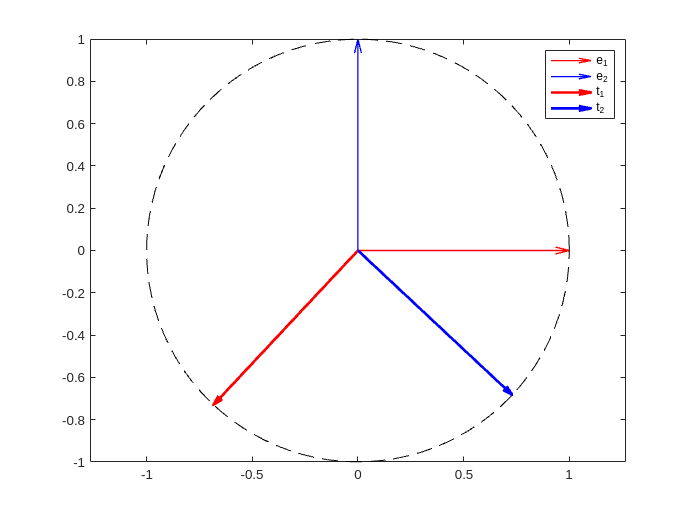


quiver(0,0,1,0, 1, 'r-', 'LineWidth',1)
hold on
quiver(0,0,0,1, 1, 'b-','LineWidth',1)
quiver(0,0,T(1,1),T(2,1), 1, 'r-', 'LineWidth',2)
quiver(0,0,T(1,2),T(2,2), 1, 'b-', 'LineWidth',2)
t=linspace(0,2*pi,100);
plot(cos(t),sin(t),'k--')
axis([-1,1,-1,1])
legend('e_1','e_2', 't_1', 't_2')
axis equal
hold off


U=[1, 1i; -1i,-1] / sqrt(2);
U'*T*U % a diagonális alak

ans =   -0.6834 - 0.7301i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.6834 + 0.7301i


### Karakterisztikus polinom, sajátértékek, sajátvektorok

`poly(x) :` az $(x-x_1)(x-x_2) \cdots (x-x_n)$ polinom együtthatói

`poly(A) :` az $A$ mátrix karakterisztikus polinomjának együtthatói

`roots(poly(A)) : az `$A$ mátrix sajátértékei

`eig(A) :` `az `$A$ mátrix sajátértékei

`[V,D] = eig(A) : Az `$A$-t diagonalizáló $V$mátrix és a sajátértékeket tartalmazó $D$ diagonális mátrix. Ha $A$ diagonalizálható: $A=V D V^{-1}$.

`V*D/V :` osztás a $V$ mátrixszal = jobbról szorzás a $V$ mátrix inverzével!

#### 3. Feladat

Ellenőrizzük, hogy az eig utasítással kapott $V$ mátrix tényleg diagonalizálja az $A$ mátrixot!

% Megoldás
A=[1,2,3;4,5,6;7,8,9];
[V,D]=eig(A);
norm(A*V-V*D)

ans = 5.2547e-15

#### 4. Feladat (HF)

Határozzuk meg az 1. előadáson és 1. gyakorlaton megadott mátrixok sajátértékeit és sajátvektorait a Matlab segítségével. Miért kaptunk néhol más eredményt?

`A=[-2,0,0; -5,-2,-5; 5,0,3];`

`A=[4,0,0; 8,4,8; 0,0,4];`

`A=[0,-1; 1,0];`

A=[-2,0,0; -5,-2,-5; 5,0,3];
[W, D] = eig(A)

W =          0         0    0.7071
    1.0000   -0.7071         0
         0    0.7071   -0.7071


D =     -2     0     0
     0     3     0
     0     0    -2


norm(A*W-W*D)

ans = 0


A=[4,0,0; 8,4,8; 0,0,4];
[W, D] = eig(A)

W =          0    0.0000         0
    1.0000   -1.0000   -1.0000
         0         0    0.0000


D =      4     0     0
     0     4     0
     0     0     4


norm(A*W-W*D)

ans = 1.2561e-15


A=[0,-1; 1,0];
[W, D] = eig(A)

W =    0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 - 0.7071i   0.0000 + 0.7071i


D =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


norm(A*W-W*D)

ans = 0